path='E:\Data\Aurelie\data\training nucbow\';
namefull=strcat(path,'test\')

namefull = 'E:\Data\Aurelie\data\training nucbow\test\'

%load suite2p 
load(strcat(path ,'Fall.mat'));

## load mask from cellpose

%import ROI from cellpose mode "save outlines as text for imagej open as
%numeric matrix
%transformation masque imagej en cellule cooblue(ncell, npixel, 1=x, 2=y)
opts = delimitedTextImportOptions;%("NumVariables", 200);
% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53", "VarName54", "VarName55", "VarName56", "VarName57", "VarName58", "VarName59", "VarName60", "VarName61", "VarName62", "VarName63", "VarName64", "VarName65", "VarName66", "VarName67", "VarName68", "VarName69", "VarName70", "VarName71", "VarName72", "VarName73", "VarName74", "VarName75", "VarName76", "VarName77", "VarName78", "VarName79", "VarName80", "VarName81", "VarName82", "VarName83", "VarName84", "VarName85", "VarName86", "VarName87", "VarName88", "VarName89", "VarName90", "VarName91", "VarName92", "VarName93", "VarName94", "VarName95", "VarName96", "VarName97", "VarName98", "VarName99", "VarName100", "VarName101", "VarName102", "VarName103", "VarName104", "VarName105", "VarName106", "VarName107", "VarName108"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
% Create an empty cell array
Names =cell(1, 300);        %need to be  increased if bigger
types  = cell(1, 300);
% Repeat the cell x times
for i = 1:300
    Names{i} = 'name';
    types{i}= 'double';
end
opts.VariableNames=Names;
opts.VariableTypes=types;
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";


bluecpoutlines = readtable(strcat(path,'aligned_blue_cp_outlines.txt'), opts);
% bluecpoutlines = readtable([path,'aligned_blue_cp_outlines.txt'], opts);
bluecpoutlines = table2array(bluecpoutlines);
% greencpoutlines = readtable(strcat(path,'aligned_green_cp_outlines.txt'), opts);
greencpoutlines = readtable(strcat(path,'modified_green_cp_outlines'), opts);
% greencpoutlines = readtable([path,'aligned_green_cp_outlines.txt'], opts);
% aligned_blue_cp_outlines.txt
greencpoutlines = table2array(greencpoutlines);
redcpoutlines = readtable(strcat(path,'aligned_red_cp_outlines.txt'), opts);
% redcpoutlines = readtable([path,'aligned_red1040_cp_outlines.txt'], opts);
redcpoutlines = table2array(redcpoutlines);


## Load calcium mask from suite2p (from Fall.mat)

m=0;
NCell=sum(iscell(:,1)>0);

for n=1 : length(stat)

    if iscell(n,1)==1
        m=m+1;

        outline_gcampx(m)={double(stat{1, n}.xext+1)};
        outline_gcampy(m)={double(stat{1, n}.yext+1)};

        neuropil(m)={stat{1, n}.neuropil_mask};

        Coomasqx(m)={double(stat{1, n}.xpix+1)};%+1  to adpat suite2p output   ONLY 1 ??????
        Coomasqy(m)={double(stat{1, n}.ypix+1)};

    end

end

## Extract coordinate cells for each color

[nbroiblue , ~]=size (bluecpoutlines);
cooblue={};

for ncell=1:nbroiblue
    n=0;
    for pix=1:2:sum (~isnan(bluecpoutlines(ncell,:)))  % le width de chaque ligne en enlevant les NaN
        n=n+1;
        cooblue(ncell,n,1) = {bluecpoutlines(ncell,pix)+1};
        cooblue(ncell,n,2) = {bluecpoutlines(ncell,pix+1)+1};
    end
end


[nbroired ,~]=size (redcpoutlines);
coored={};

for ncell=1:nbroired
    n=0;
    for pix=1:2:sum (~isnan(redcpoutlines(ncell,:)))  % le width de chaque ligne en enlevant les NaN
        n=n+1;
        coored(ncell,n,1) = {redcpoutlines(ncell,pix)+1};
        coored(ncell,n,2) = {redcpoutlines(ncell,pix+1)+1};
    end

end

[nbroigreen, count]=size (greencpoutlines);
coogreen={};

for ncell=1:nbroigreen
    n=0;
    for pix=1:2:sum (~isnan(greencpoutlines(ncell,:)))  % le width de chaque ligne en enlevant les NaN
        n=n+1;
        coogreen(ncell,n,1) = {greencpoutlines(ncell,pix)+1};
        coogreen(ncell,n,2) = {greencpoutlines(ncell,pix+1)+1};
    end
end


## Calculation of centroid

% tic 

gcamp_centroid=zeros(NCell,2);

for n=1:NCell

    gcamp_centroid(n,:)=[mean(cell2mat(Coomasqx(1,n))),mean(cell2mat(Coomasqy(1,n)))];

end

blue_centroid=zeros(nbroiblue,2);

for n=1:nbroiblue
    blue_centroid(n,:)=[mean(cell2mat(cooblue(n,:,1))),mean(cell2mat(cooblue(n,:,2)))];
end

%making  red mask (binary) for comparison

red_centroid=zeros(nbroired,2);

for n=1:nbroired
    red_centroid(n,:)=[mean(cell2mat(coored(n,:,1))),mean(cell2mat(coored(n,:,2)))];
end

%making  red mask (binary) for comparison

green_centroid=zeros(nbroired,2);

for n=1:nbroigreen
    green_centroid(n,:)=[mean(cell2mat(coogreen(n,:,1))),mean(cell2mat(coogreen(n,:,2)))];
end
 % toc

## calculation distance centroid with gcamp only

distance_red=zeros(nbroired,NCell);
distance_blue=zeros(nbroiblue,NCell);
distance_green=zeros(nbroigreen,NCell);

for m = 1:nbroired
    for n = 1:NCell
        distance_red (m,n) = sqrt((red_centroid(m,1) - gcamp_centroid(n,1))^2 + (red_centroid(m,2) - gcamp_centroid(n,2))^2);
    end
end
for m = 1:nbroiblue
    for n = 1:NCell
        distance_blue (m,n) = sqrt((blue_centroid(m,1) - gcamp_centroid(n,1))^2 + (blue_centroid(m,2) - gcamp_centroid(n,2))^2);
    end
end
for m = 1:nbroigreen
    for n = 1:NCell
        distance_green (m,n) = sqrt((green_centroid(m,1) - gcamp_centroid(n,1))^2 + (green_centroid(m,2) - gcamp_centroid(n,2))^2);
    end
end

## Threshold centroid and IoU to find overlap


threshold=3;
thresholdIoU=0.5;

maskmulti=zeros(NCell,3); % 1 red, 2 green ,3 blue, 4 redgreen,5 redblue, 6 bluegreen , 7all, 8 none


% [x, y]=find (distance_red<=threshold & IoURG >= thresholdIoU);  
[x, y]=find (distance_red<=threshold );  

maskmulti(y,1)=1; %red true

% [x, y]=find (distance_green<=threshold & IoUGG >= thresholdIoU);
[x, y]=find (distance_green<=threshold );

maskmulti(y,2)=1 ;   %green=true

% [x, y]=find (distance_blue<=threshold & IoUBG >= thresholdIoU);
[x, y]=find (distance_blue<=threshold );

maskmulti(y,3)=1; %blue true 
colorcell=zeros(NCell,1);

for n=1:NCell

    if maskmulti(n,1)==true && all(maskmulti(n,2:3)==0)       %red
        colorcell(n)=1;

    elseif maskmulti(n,2)==true && all(maskmulti(n,[1,3])==0) % green
        colorcell(n)=2;

    elseif maskmulti(n,3)==true && all(maskmulti(n,1:2)==0) %blue
        colorcell(n)=3;

    elseif maskmulti(n,1)==true &&  maskmulti(n,2)==true &&   maskmulti(n,3)==false     %yellow 4
        colorcell(n)=4;

    elseif maskmulti(n,1)==true &&  maskmulti(n,2)==false &&   maskmulti(n,3)==true   %magenta 5
        colorcell(n)=5;

    elseif maskmulti(n,1)==false &&  maskmulti(n,2)==true &&   maskmulti(n,3)==true  %cyan 6
        colorcell(n)=6;

    elseif maskmulti(n,1)==true &&  maskmulti(n,2)==true &&   maskmulti(n,3)==true  % all 7
        colorcell(n)=7;

    else
        colorcell(n)=8;

    end
end 

## Calcul color all cells

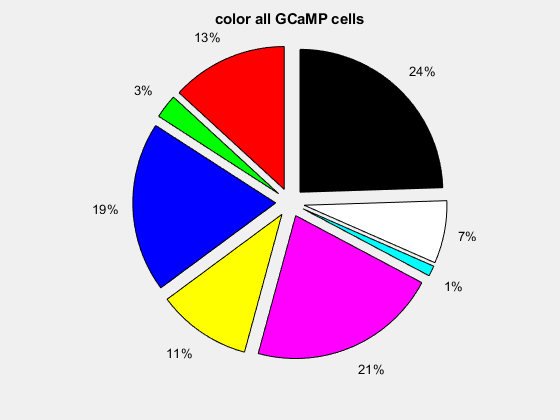


nbR=sum(colorcell==1);
nbG=sum(colorcell==2);
nbB=sum(colorcell==3);
nbRG=sum(colorcell==4);
nbRB=sum(colorcell==5);
nbGB=sum(colorcell==6);
nball=sum(colorcell==7);
nbnone=sum(colorcell==8);

total=nbR+nbG+nbB+nbRG+nbRB+nbGB+nball+nbnone;
    
color_all=[nbR nbG nbB nbRG nbRB nbGB nball nbnone];
labels = {'Red','Green','Blue' 'Red/Green' 'Red/Blue' 'Green/Blue' 'All' 'none'};
explode = [1 1 1 1 1 1 1 1];
fig = figure('visible','on');
pie(color_all, explode)
colormap([1 0 0;      %// red
          0 1 0;      %// green
          0 0 1;      %// blue
          1 1 0; %YELLOW
          1 0 1; %magenta
          0 1 1; %cyan
          1 1 1;
          0 0 0])  %white
          
title 'color all GCaMP cells'

namegraph=strcat(namefull ,'color_all_GCaMP_cells.png');

    if isfolder(namefull)
        exportgraphics(gcf,namegraph,'Resolution',300);
        close gcf
    end


## Calcul color all cells

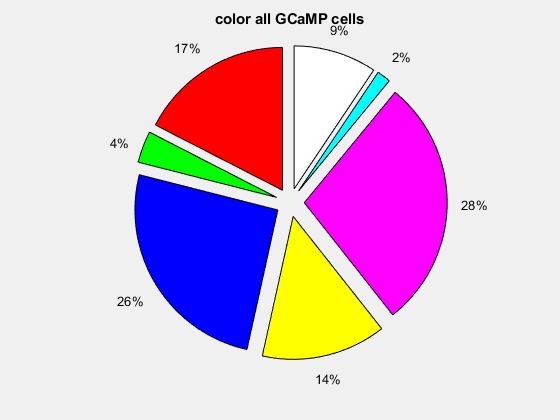


nbR=sum(colorcell==1);
nbG=sum(colorcell==2);
nbB=sum(colorcell==3);
nbRG=sum(colorcell==4);
nbRB=sum(colorcell==5);
nbGB=sum(colorcell==6);
nball=sum(colorcell==7);
nbnone=sum(colorcell==8);

total=nbR+nbG+nbB+nbRG+nbRB+nbGB+nball;
    
color_all=[nbR nbG nbB nbRG nbRB nbGB nball ];
labels = {'Red','Green','Blue' 'Red/Green' 'Red/Blue' 'Green/Blue' 'All' };
explode = [1 1 1 1 1 1 1 ];
fig = figure('visible','on');
pie(color_all, explode)
colormap([1 0 0;      %// red
          0 1 0;      %// green
          0 0 1;      %// blue
          1 1 0; %YELLOW
          1 0 1; %magenta
          0 1 1; %cyan
          1 1 1;
          ])  %white
          
title 'color all GCaMP cells'